sys_info = stepinfo(linsys1_dolne)

sys_info = 3×1 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


ans = 0.1941

ans = 0

ans = 1.9431


sys_closed =
 
  A = 
             x1        x2        x3
   x1         0         1         0
   x2    -59.01    -20.66  -0.06979
   x3      5041      1821     6.739
 
  B = 
           u1
   x1       0
   x2  -5.237
   x3   488.6
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.



Undefined operator '==' for input arguments of type 'ss'.

Error in sinfo (line 26)
if sys(1,1)==-Inf,

sys_info.RiseTime

A_closed = A - B*K;
B_closed = B;
C_closed =  C - D*K;
D_closed = D;
sys_closed = ss(A_closed, B_closed, C_closed, D_closed)
sys_info = ssinfo(sys_closed)
sys_info.RiseTime

 ss2tf  State-space to transfer function conversion.
    [NUM,DEN] = ss2tf(A,B,C,D,iu)  calculates the transfer function:
 
                NUM(s)          -1
        H(s) = -------- = C(sI-A) B + D
                DEN(s)
    of the system:
        .
        x = Ax + Bu
        y = Cx + Du
 
    from the iu'th input.  Vector DEN contains the coefficients of the
    denominator in descending powers of s.  The numerator coefficients
    are returned in matrix NUM with as many rows as there are 
    outputs y.
 
    See also tf2ss, zp2tf, zp2ss.



--- help for ss ---

 ss  Construct state-space model or convert model to state space.
 
   Construction:
     SYS = ss(A,B,C,D) creates an object SYS representing the continuous- 
     time state-space model
          dx/dt = Ax(t) + Bu(t)
           y(t) = Cx(t) + Du(t)
     You can set D=0 to mean the zero matrix of appropriate size. SYS is 
     of type ss when A,B,C,D are numeric arrays, of type GENSS when 
     A,B,C,D depend on tunable parameters (see REALP and GENMAT), and 
     of type USS when A,B,C,D are uncertain matrices (requires Robust 
     Control Toolbox).
 
     SYS = ss(A,B,C,D,Ts) creates a discrete-time state-space model with
     sample time Ts (set Ts=-1 if the sample time is undetermined).
 
     SYS = ss creates an empty ss object.
     SYS = ss(D) specifies a static gain matrix D.
 
     You can set additional model propertie

help('ss2tf')
help(ss)

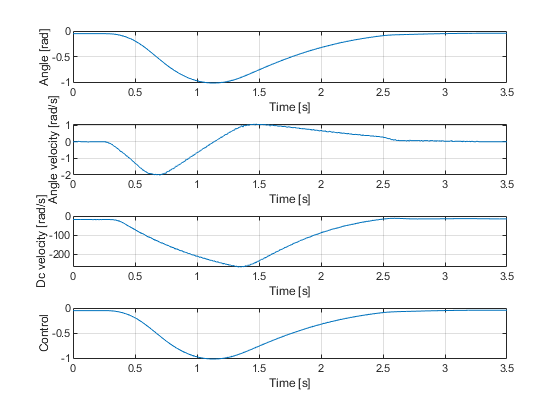

pomiary = test1_stan_aperiodyczny;
time = pomiary.time;
angle = pomiary.signals(1).values;
angle_vel = pomiary.signals(4).values;
dc_vel = pomiary.signals(6).values;
control = pomiary.signals(8).values;

angle = angle(3190:3540);
time = time(3190:3540) - time(3190);
angle_vel = angle_vel(3190:3540);
dc_vel = dc_vel(3190:3540);
control = control(3190:3540);

figure('Name','Aperiodyczny')
subplot(4, 1, 1)
plot(time, angle)
xlabel('Time [s]')
ylabel('Angle [rad]')
% subtitle("Wychylenie wahadła")
grid on
subplot(4, 1, 2)
plot(time, angle_vel)
xlabel('Time [s]')
ylabel('Angle velocity [rad/s]')
% subtitle("Prędkość kątowa wahadła")
grid on
subplot(4, 1, 3)
plot(time, dc_vel)
xlabel('Time [s]')
ylabel('Dc velocity [rad/s]')
% subtitle("Prędkość silnika")
grid on
subplot(4, 1, 4)
plot(time, angle)
xlabel('Time [s]')
ylabel('Control')
% subtitle("Sterowanie")
grid on

calkowy_wskaznik = sum(abs(angle))

calkowy_wskaznik = 122.8721

angle_max = max(angle)

angle_max = -0.0446

angle_min = min(angle)

angle_min = -1.0100

uchyb_max = angle_min

uchyb_max = -1.0100


for i=30:351
    if(abs(angle(i)) < 0.05)
        i_ustalone = i;
        t_ustalone = time(i);
        break;
    end
end
t_ustalone

t_ustalone = 3.0200

przeregulowanie = 0 %wartośs angle max i angle min maja ten sam znak

przeregulowanie = 0

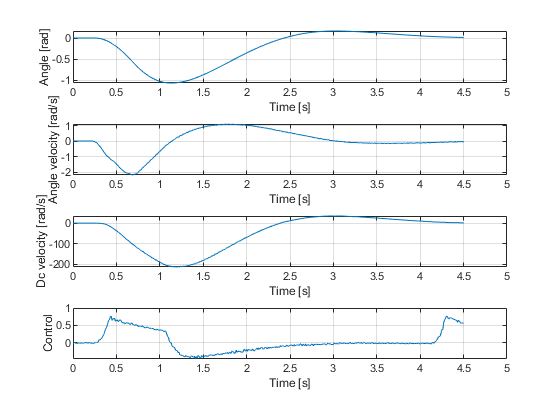

pomiary = test3_stan_oscylacyjny;
time = pomiary.time;
angle = pomiary.signals(1).values;
angle_vel = pomiary.signals(4).values;
dc_vel = pomiary.signals(6).values;
control = pomiary.signals(8).values;

angle = angle(1450:1900);
time = time(1450:1900) - time(1450);
angle_vel = angle_vel(1450:1900);
dc_vel = dc_vel(1450:1900);
control = control(1450:1900);
% current = current(1450:1900);

figure('Name','Oscylacyjny')
subplot(4, 1, 1)
plot(time, angle)
xlabel('Time [s]')
ylabel('Angle [rad]')
% subtitle("Wychylenie wahadła")
grid on
subplot(4, 1, 2)
plot(time, angle_vel)
xlabel('Time [s]')
ylabel('Angle velocity [rad/s]')
% subtitle("Prędkość kątowa wahadła")
grid on
subplot(4, 1, 3)
plot(time, dc_vel)
xlabel('Time [s]')
ylabel('Dc velocity [rad/s]')
% subtitle("Prędkość silnika")
grid on
subplot(4, 1, 4)
plot(time, current)
xlabel('Time [s]')
ylabel('Control')
% subtitle("Sterowanie")
grid on

wskaznik_uchybu = sum(abs(angle))

wskaznik_uchybu = 143.4015

calkowy_wskaznik = sum(abs(angle))

calkowy_wskaznik = 143.4015

angle_max = max(angle)

angle_max = 0.1703

angle_min = min(angle)

angle_min = -1.0647

uchyb_max = angle_min

uchyb_max = -1.0647


for i=30:351
    if(abs(angle(i)) < 0.05)
        i_ustalone = i;
        t_ustalone = time(i);
        break;
    end
end
t_ustalone

t_ustalone = 0.2900

przeregulowanie = abs(angle_max)/abs(angle_min)* 100

przeregulowanie = 15.9929